clc;
clear;

solve for theta

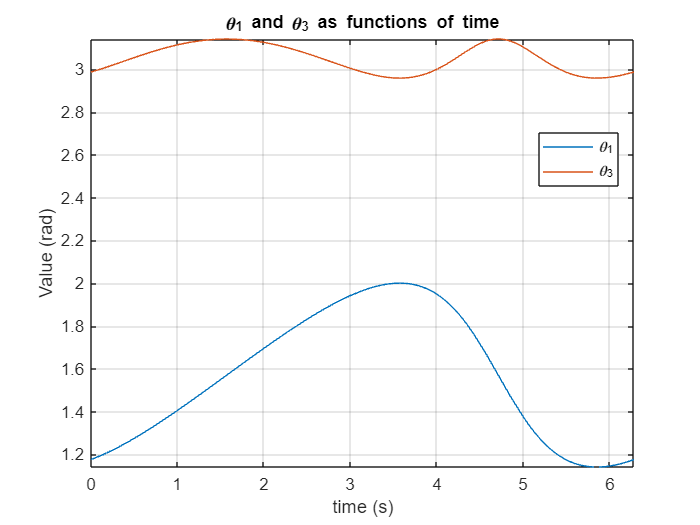

% init info
syms theta1 theta2 theta3 ao1 co1x;
o1o2 = 12;
ao2 = 5;
bo1 = 32;
bc = 16;
co1y = 32;

% equations for solve
eqns = [
    o1o2 + ao2 * sin(theta2) == ao1 * sin(theta1);
    ao2 * cos(theta2) == ao1 * cos(theta1);
    bo1 * sin(theta1) + bc * sin(theta3) == co1y;
    bo1 * cos(theta1) + bc * cos(theta3) - co1x == 0;
];

slv = solve(eqns, [theta1, theta3, ao1, co1x]);

theta1_expr = slv.theta1(2);
theta3_expr = slv.theta3(2);
co1x_expr = slv.co1x(2);
ao1_expr = slv.ao1(2);

% disp(['theta1 = ', char(simplify(theta1_expr))]);
% disp(['theta3 = ', char(simplify(theta3_expr))]);

% Plot theta1 and theta3 as functions of time
figure;
fplot(theta1_expr, [0, 2*pi]);
hold on;
fplot(theta3_expr, [0, 2*pi]);
xlabel('time (s)');
ylabel('Value (rad)');
legend('\theta_1', '\theta_3');
title('\theta_1 and \theta_3 as functions of time');
grid on;
legend("Position", [0.77274,0.64579,0.10964,0.10214])

velocities

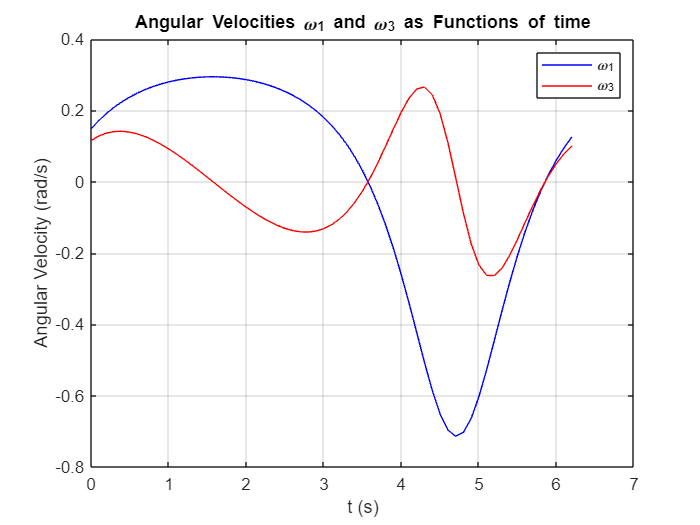

omega1 = diff(theta1_expr);
omega3 = diff(theta3_expr);
vc = diff(co1x_expr);

% Plot omega1 and omega3 as functions of time
theta2_range = 0 : 0.1 : 2 * pi;
omega1_values = subs(omega1, theta2, theta2_range);
omega3_values = subs(omega3, theta2, theta2_range);
vc_values = subs(vc, theta2, theta2_range);

figure;
plot(theta2_range, omega1_values, 'b', 'DisplayName', '\omega_1');
hold on;
plot(theta2_range, omega3_values, 'r', 'DisplayName', '\omega_3');
xlabel('t (s)');
ylabel('Angular Velocity (rad/s)');
title('Angular Velocities \omega_1 and \omega_3 as Functions of time');
legend;
grid on;

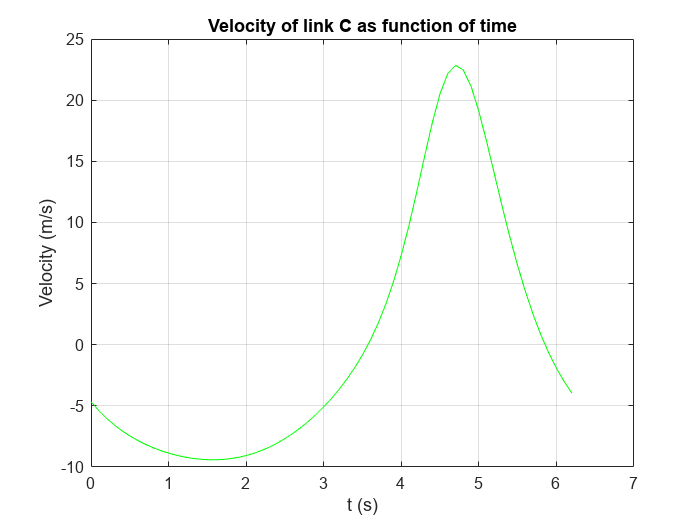

figure;
plot(theta2_range, vc_values, 'g', 'DisplayName', 'V_C');
xlabel('t (s)');
ylabel('Velocity (m/s)');
title('Velocity of link C as function of time');
grid('on');

accelerations

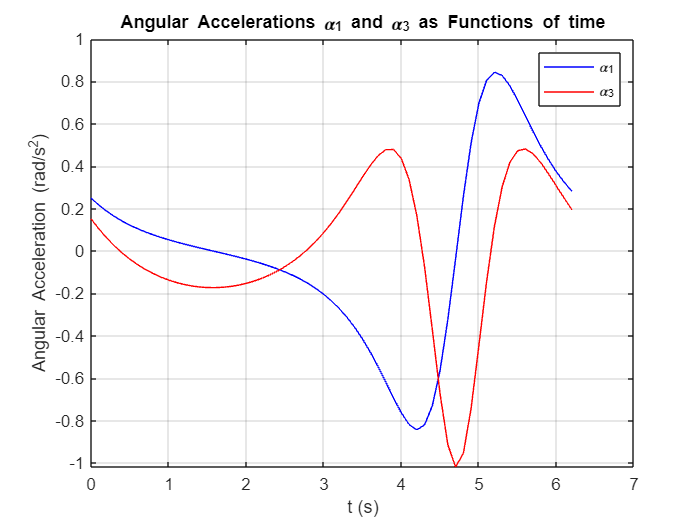

alpha1 = diff(omega1);
alpha3 = diff(omega3);
ac = diff(vc, theta2);

% Plot alpha1 and alpha3 as functions of time
theta2_range = 0 : 0.1 : 2 * pi;
alpha1_values = subs(alpha1, theta2, theta2_range);
alpha3_values = subs(alpha3, theta2, theta2_range);
ac_values = subs(ac, theta2, theta2_range);

figure;
plot(theta2_range, alpha1_values, 'b', 'DisplayName', '\alpha_1');
hold on;
plot(theta2_range, alpha3_values, 'r', 'DisplayName', '\alpha_3');
xlabel('t (s)');
ylabel('Angular Acceleration (rad/s^2)');
title('Angular Accelerations \alpha_1 and \alpha_3 as Functions of time');
legend;
grid on;

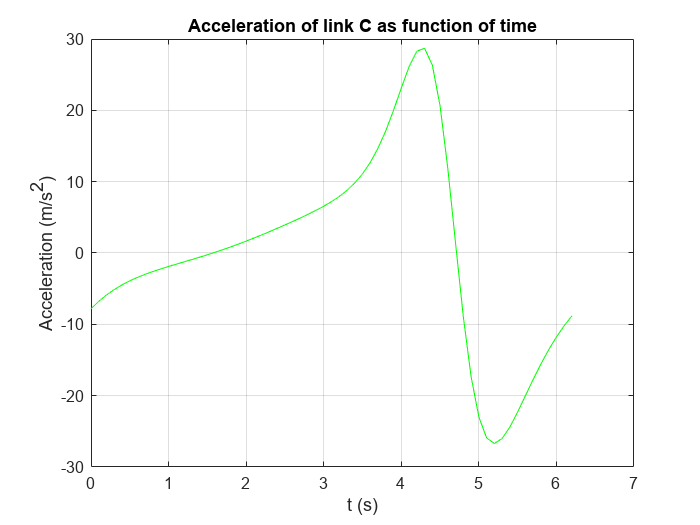

figure;
plot(theta2_range, ac_values, 'g', 'DisplayName', 'a_C');
xlabel('t (s)');
ylabel('Acceleration (m/s^2)');
title('Acceleration of link C as function of time');
grid('on');

animation

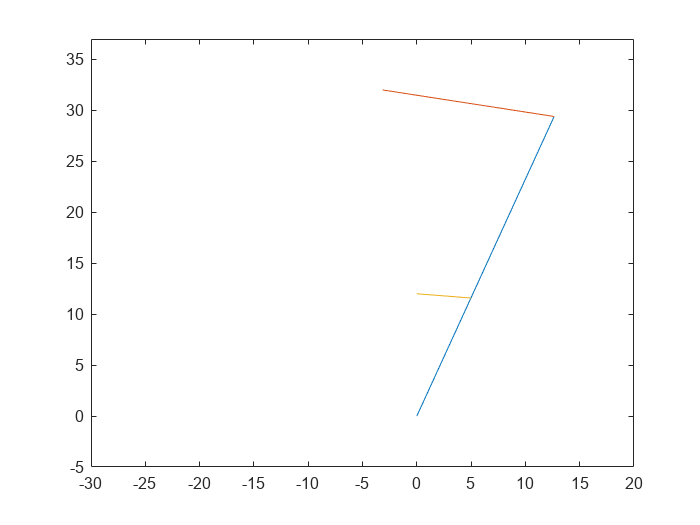

theta1_values = subs(theta1_expr, theta2, theta2_range);
theta3_values = subs(theta3_expr, theta2, theta2_range);
co1x_values = subs(co1x_expr, theta2, theta2_range);
ao1_values = subs(ao1_expr, theta2, theta2_range);
for i = 1:length(theta2_range)
    pause(0);
    clf();

    plot([0, bo1*cos(theta1_values(i))], [0, bo1*sin(theta1_values(i))]);
    hold on;
    plot([bo1*cos(theta1_values(i)), co1x_values(i)], [bo1*sin(theta1_values(i)), co1y]);
    hold on;
    plot([0, ao1_values(i)*cos(theta1_values(i))], [o1o2, ao1_values(i)*sin(theta1_values(i))]);
    hold on;
    xlim([-30, 20]);
    ylim([-5, co1y+5]);
end